### Get cell and nucleoid morphology

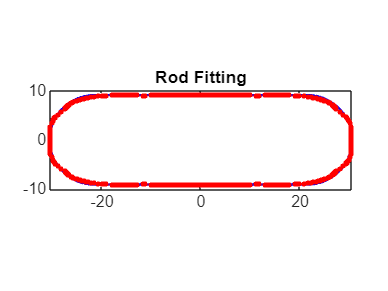

Rfit = 9.06;  Lfit = 21.52.
The mean squared error is 0.12580


% Visualizing rod shape fitting for cell outline
[Rfit,Lfit,resd_avg] = Rod_Morph_fit(cell_outline,num_pix_y,aspt_ratio,'on');


% nucleoid ratio: length, width, area
% cell and nucleoid parameter: length, width (normalized by cell width)
[Nuc_ratio_spMap, cell_para, nuc_para] = NucRatio(cell_outline, nuc_contour{1}, aspt_ratio, num_pix_y, 'on')

Nuc_ratio_spMap =     0.7128    0.3600    0.2417


cell_para =     3.3746    1.0000


nuc_para =     2.4053    0.3600


disp('=============================================')

### Cell and nucleoid *in silico* geometry construction 

%% parameter set up for effective area (inner membrane)
Ro=5;   % width of cell rod is always 2*Ro, 10 in this case 
convert_factor = Ro/Rfit;    % scale Rfit to Ro (5), geometry generalization for simulation 
Lo = Lfit*convert_factor;
Lo = round(Lo*10)/10;       % get Lo used in cell rod model 

%% Take cell outline into consideration 
scaling_width = num_pix_y*convert_factor/2;              % 0.5*cell width in simulation (used for coordinate normalization)
scaling_length = num_pix_y*aspt_ratio*convert_factor/2;  % 0.5*cell length in simulation (used for coordinate normalization)
scale_bar = cell_avg_width/(2*scaling_width)*1000   % 1 unit in simulation = scale_bar nm

scale_bar = 94.2727

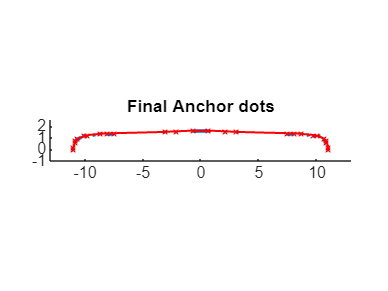


%% Get anchor points from nucleoid boundary to simplify piecewise function
% oringinal nucleoid outline by exclusion trend in htMap
[anchor_htMap,kb_nuc_htMap] = NucAnchor(nuc_outline,aspt_ratio,convert_factor,num_pix_y,'anchor_final');

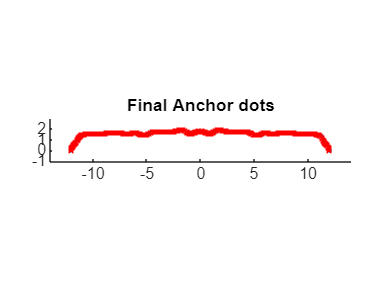

% contour nucleoid outline by spMap
[anchor_spMap,kb_nuc_spMap] = NucAnchor(nuc_contour{1},aspt_ratio,convert_factor,num_pix_y,'anchor_final');

Geometry_Reconstruct_2D(Ro, Lo, scaling_width, scaling_length, anchor_htMap, anchor_spMap)

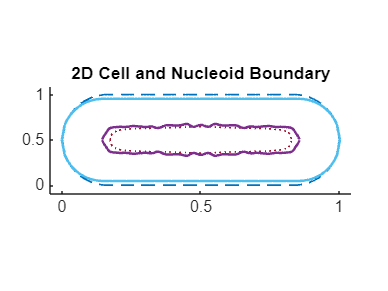

SaveFigure(result_folder,'Reconstructed Geometry 2D',...
    gcf, {'fig','png','svg'},'jet')

Geometry_Reconstruct_3D(Ro, Lo, scaling_width, scaling_length, anchor_spMap)

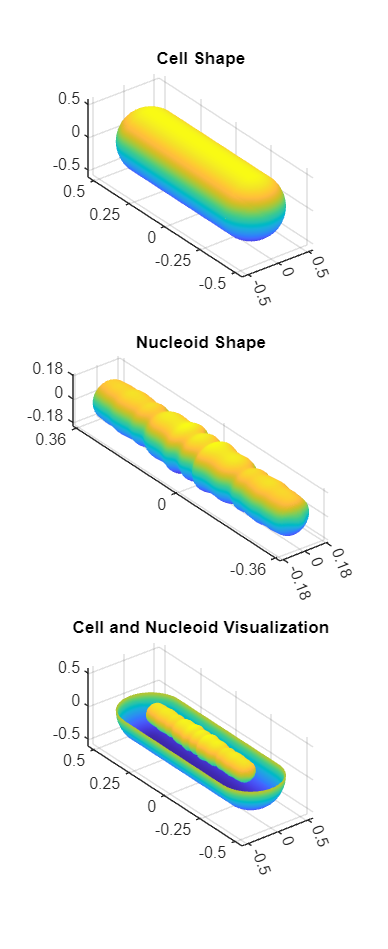

Save3DFig(result_folder,'Reconstructed Geometry 3D',...
    gcf, {'fig','png','svg'},slanCM('parula'))